clc; clear all; clf;

# Avance 2: Entrenamiento, adecuacion y evaluacion de modelos

Para este avance se tomaran los diferentes datasets obtenidos en el avance 1 y se procedera a buscar el mejor/mejores modelos de clasificacion para predecir la posibilidad de intento de suicidio recurrente.

En un primer momento se probaran diferentes modelos , haciendo uso de la herramienta   "Classification Learner" de Matlab, debido a  su facilidad y rapidez para probar multiples modelos simultaneamente. Se tomaran los pares dataset-modelo que mejores resultados den (preferiblemente por encima de 70% de acierto) para seguirlos desarrollando, en terminos de seleccion de parametros y optimizacion de hiperparametros.

Para la seleccion de parametros y ajuste de hiperparametros, en donde sea posible se usaran herramientas las interactivas o automaticas que provee Matlab. 

Como metodos de validacion y calificacion de los modelos se prentenden usar los dados a continuacion `(To Do: añadir breve descripcion de cada uno)`

- Score

- Matriz de confusion

- ROC curve

- F1

Al momento de realizar predicciones se generaran dos, una deterrministica y otra probabilistica.

### **Data sets de entrada.**

En el avance 1 se obtuvieron 4 datasets despues del proceso de limpieza, los cuales se mencionan a continuacion:

- cds_imputed : dataset con 33 carateristicas y 4146 registros

- cds : dataset con 28 caracteristicas 4146 registros, 

- cds_few : dataset 33 caracteristicas y 655 registros

- cds_fem_minus_alcohol:  dataset 32 caracteristicas 1690 registros.

%cds = readtable('cds.csv'); size_cds = size(cds)
cds_imputed = readtable('cds_imputed.csv'); size_imputed = size(cds_imputed)

size_imputed =         4146          34


cds_imputed = movevars(cds_imputed,'inten_prev','after','tipo_ss_S');
%cds_few = readtable('cds_few.csv'); size_few = size (cds_few)
%cds_few_minus_alcohol = readtable('cds_few_minus_alcohol.csv');
%       size_few_minus_alcohol = size (cds_few_minus_alcohol)

Con estos dataset se procede realizar un enntrenamiento exploratorio de modelos , para  continuar con los mas prometedores. Sin embargo, es necesarion definir el concepto de "mas prometedor". En este primer momento se tendra en cuanta la exactitud de los modelos

Es de utilidad tener en cuenta que para el entrenamiento de los modelos fue usada validacion cruzaada con "k-folds"( k=5) ,asi, el valor de la exactitud presentado corresponde a la exactitud de validacion y esta sirve como un estimado del desempeño del modelo en nuevos datos comparados con el conjunto de entrenamiento.

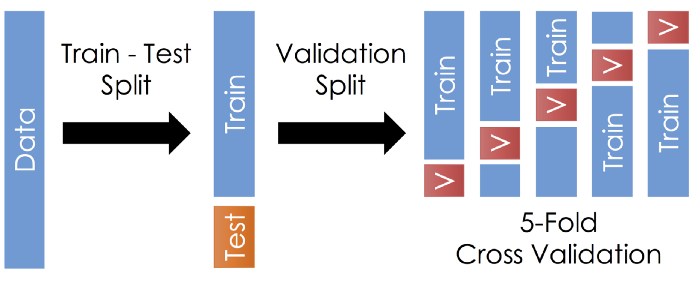

**Resultados cds**

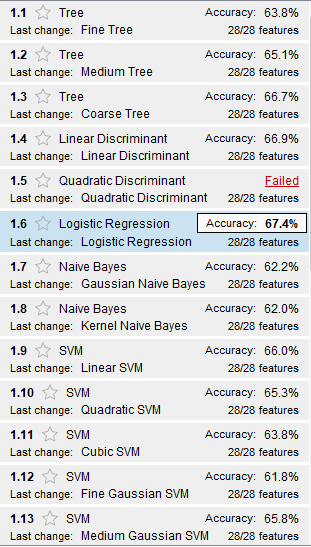

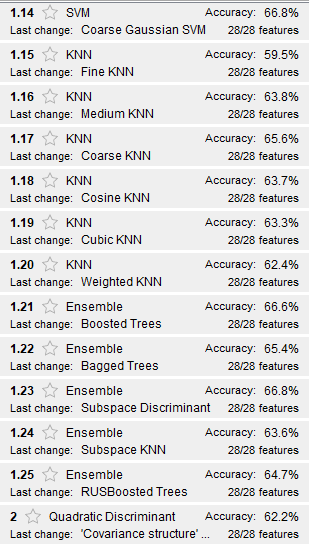

**Resultados cds_imputed**

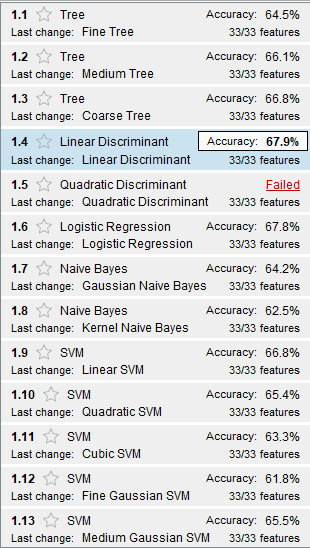

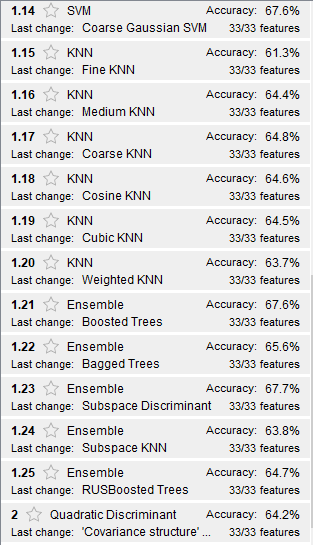

**Resultados cds_few**

Para este dataset algunos modelos se hicieron individualmente, porque presentaban problemas con las caracteristicas 'antec_tran', 'tipo_ss_I', 'suici_fm_a' y 'tipo_SS_P ya que la mayoria o casi todos sus valores son iguales por lo que no aportan informacion  o no presentan variacion con respecto a una de las clases por hallar.

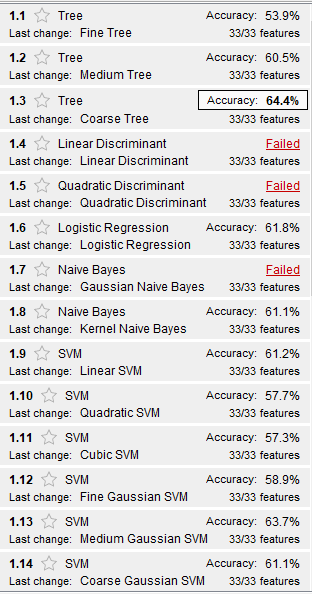

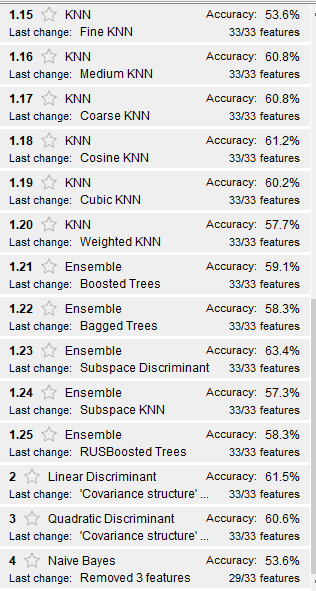

**Resultados cds_few_minus_alcohol**

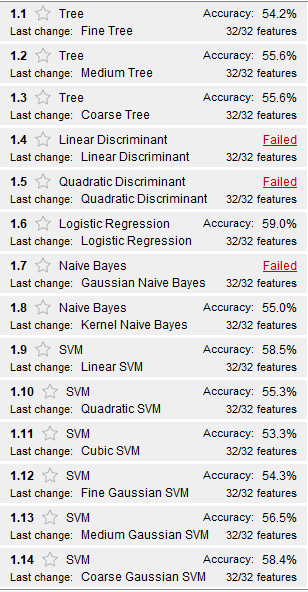

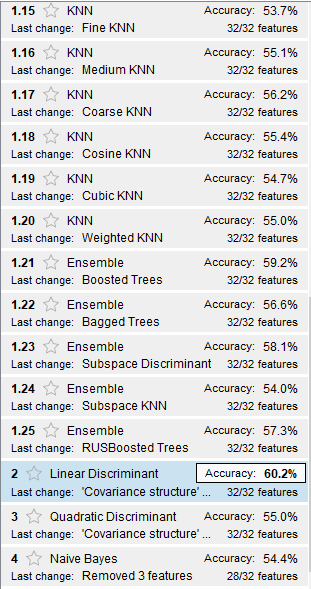

Por motivos exploratorios se realizaron pruebas aplicandole PCA a los datos, pero los resultadon en general fueron inferiores a los obtenidos sin esta transformacion, por lo que esta transformacion de los datos no sera utilizada. `(¿Uno si deberia hacer PCA en datos categoricos?`***) ***

Como se puede notar, ningun par dataset-modelo obtuvo una precision mayor al 70% tal y como se habia definido inicialmente para su aceptacion. Por este motivo se tomara aquel dataset que produjo el modelo con la mayor precision(cds_imputed) y los mejores modelos obtenidos a partir de este -Coarse Tree, Linear discriminant, Logistic regresion , SVM (linear y coarse) y Ensamble(BoostTrees, SubsD)-

### **Feature selection**

Bucando reducir la dimensionalidad y explorar direferente opciones se pretende realizar un proceso de seleccion de caracteriscas. Esto se hara filtrando aquellas caracteristicas menos importantes para la respuesta 'inten_prev' mediante el algoritmo MRMR(Minimum Redundancy Maximun Relevance), del cual se puede obtener el "ranking" de importancia de los predictores teniendo en cuentas la respuesta.

Se entrenaran 2 modelos, uno con todas las caracteristicas y adicionalmente otro con el conjunto de las 7 mas importantes

idx = fscmrmr(cds_imputed,'inten_prev');
most_signif_features = cds_imputed.Properties.VariableNames(idx(1:7)).'

most_signif_features = 7×1 cell array
    {'antec_tran'}
    {'hist_famil'}
    {'muerte_fam'}
    {'antec_v_a' }
    {'prob_consu'}
    {'plan_suici'}
    {'gp_psiquia'}


less_signif_features =cds_imputed.Properties.VariableNames(idx(end-4:end)).'

less_signif_features = 5×1 cell array
    {'escolarid' }
    {'esco_educ' }
    {'tipo_ss_C' }
    {'trab_socia'}
    {'sexo_'     }


### **Optimizacion de hiperparametros**

Para la optimizacion de hiperparametros seran utilizados dos enfoques:

Para los modelos simples(e.g. arboles de decision) se realizara mediante GridSearch, mientras que para los mas complejos(Ensamble, SVM) sera utilizado un metodo de optimizacion bayesiana, el cual, a travez de 30 iteraciones se va redirigiendo hacia aquellos hiperparametros del espacio de busqueda que proveen mejores resultados para el modelo. Este eleccion se hace debido a los costos computacionales elevados de realizar Grid o Random Serch en modelos complejos.

Como parte del proceso de optimizacion se obtiene el gráfico de error de clasificación mínimo en el cual se encuentran principalmente :

- Los resultados de la optimizacion

- El mínimo error de clasificación observado(puntos azules) hasta la iteracion actual

- Bestpoint hyperparameters(cuadrado rojo), indica la iteracion que corresponde a los valores de los hiperparametros optimizados

En general hubo un deempeño un poco mas alto usanto todas las caracteristicas del dataset que usando las 7 mas importantes

Mínimo error de clasificación

Iteración

Mínimo error de clasificación observado

Hiperparámetros de error mínimo 

Los resultados se presentaran a continuacion para cada modelo:

Arboles de decision:

En la anterior etapa mejores resultados fueron obtenidos con arboles de decision gruesos(con poco numero de splits), lo cual es confirmado con los resultados de este proceso

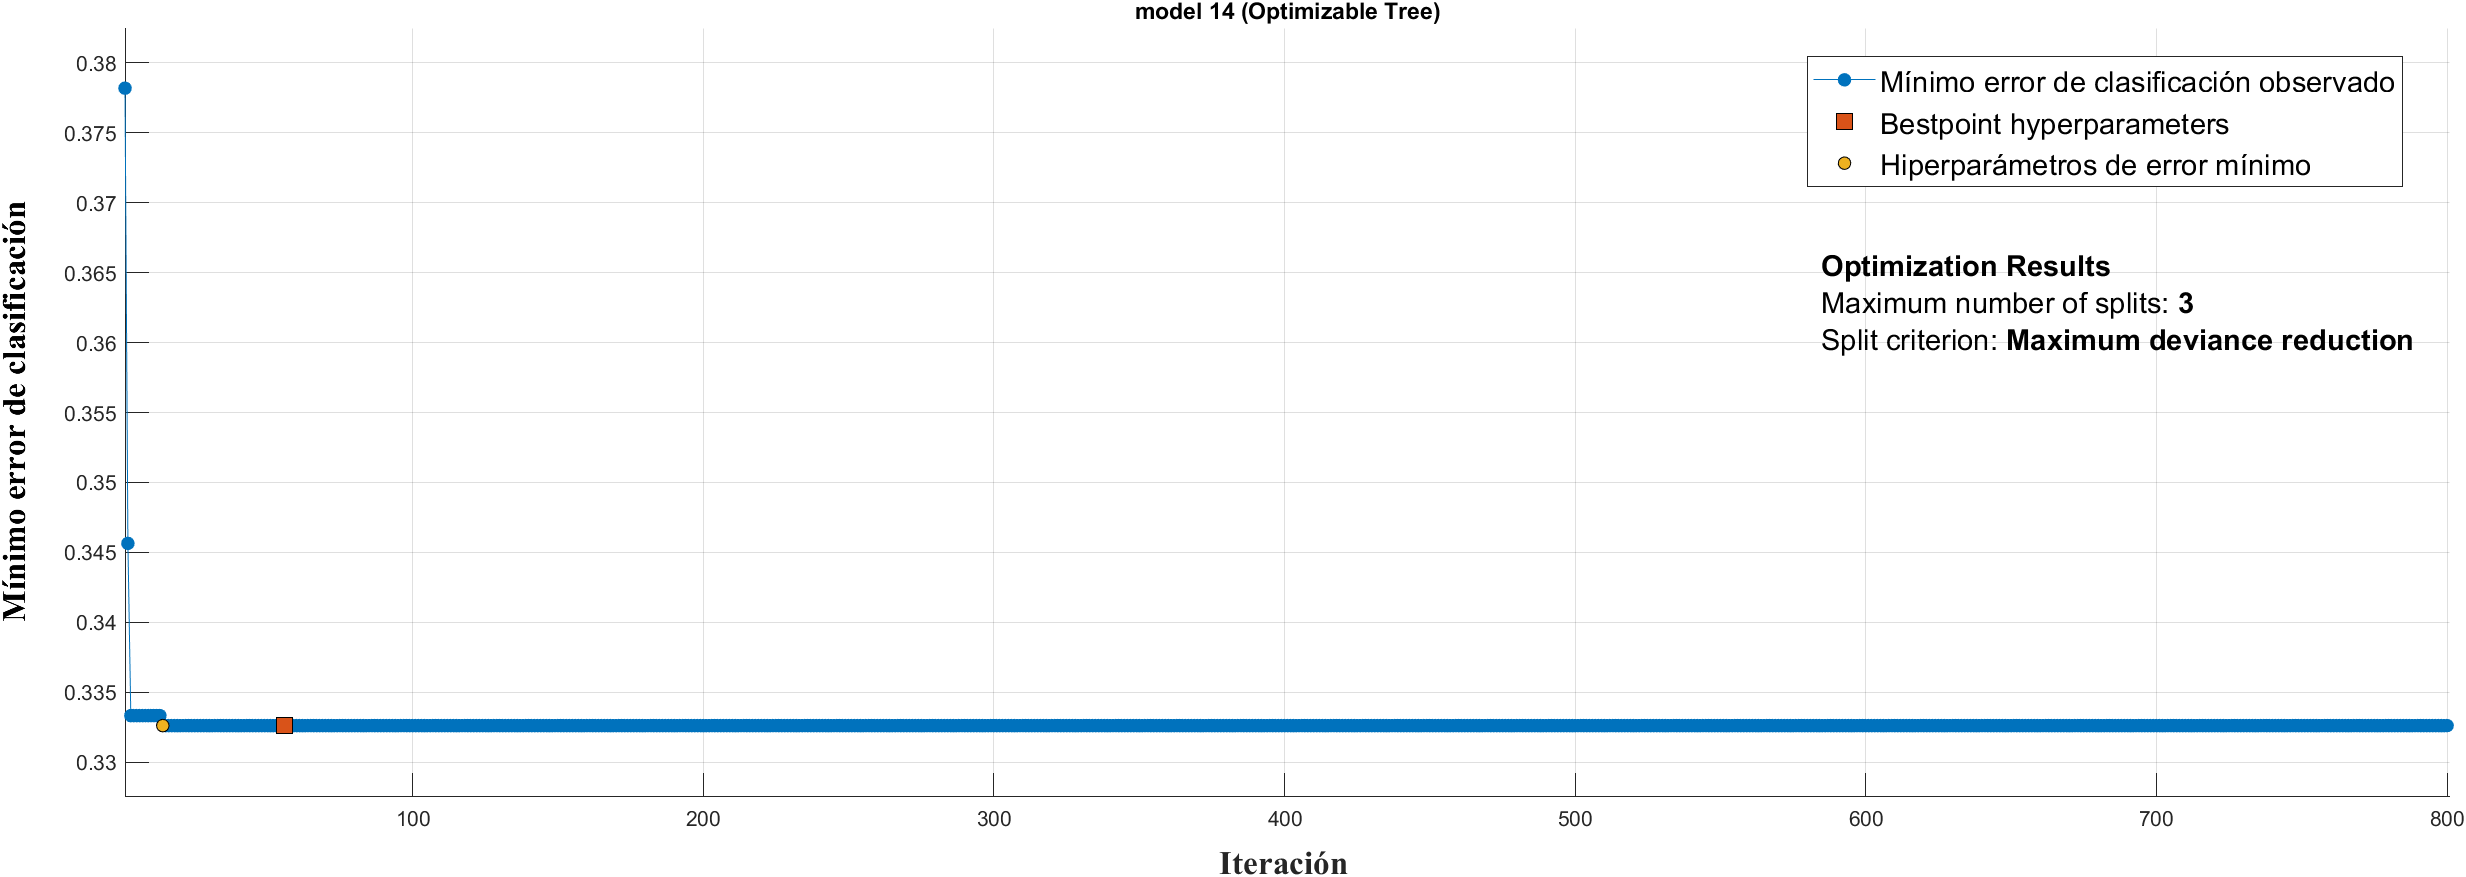

**Arboles de decision( 7 caracteristicas):**

Para este caso los mejore resultados fueron con arboles finos

Discriminante: 

Anteriormente se habia hallado que el lineal era el que mejores resultados presentaba, esto se comprueba/reafirma al raelizar este paso.

Las combinaciones disponibles para este tipo de modelos son pocas por lo que con pocas iteraciones es suficiente

Discriminante(7 caracteristicas):

Logistic regression:

Este modelo no presenta hiperparametros para ajustar.

SVM:

Ensamble:

### **Presentacion de resultados de los modelos entrenados con el data set completo y el de caracteristicas reducidas**

`HAcerlo en terminos de matriz de confusion. ROC,...`

### **Comparacion de modelos**

 Para este punto se tendran en cuenta varias cosas:

- La precision y exactitud del modelo, mientras mayor mejor, sin llegar a un caso de sobreajuste.

- El numero de parametros, en general es de interes obtener modelos que con un bajo numero de parametros sean capaces de cumplir con su objetivo a cabalidad, esto debido a que en un caso real es mas dificil y costoso, en terminos de dinero y tiempo obtener una cantidad grande de informacion.En este caso no se le dara mayor importancia a unos parametros sobre otros, solo sera de interes el numero de ellos.

- Un ultimo factor que se tendra en cuenta para preferir un modelo sobre otro, es la distribcuion de falsos negativos hacia cierta clase particular, i.e.  en este contexto no seria nada bueno identificar erroneamente a aquellas personas con tendencia repetitiva al intento de suicidio, mientras que identificar erroneamente a aquellos que en realidad no(falso positivo), seria mas aceptable.

`When you open the plot, the rows show the true class, and the columns show the predicted class. If you are using holdout or cross-validation, then the confusion matrix is calculated using the predictions on the held-out observations. The diagonal cells show where the true class and predicted class match. If these diagonal cells are blue, the classifier has classified observations of this true class are classified correctly`.

### **Conclusiones**

`El por que nuestros modelos son tan malos(posibles razones:) y como seria excelente de acuerdo a la propuesta inicial poder consefuir datasets con informacion de personas que han intentando previamente el sucisdio como de aquella que no`

`Sugeridos por el profesor: Regresion logistica, SVM, Arboles de decision, Redes neuronales, LMP, Random Fores`

`Intent_prev{1 = SI; 2 = NO}`

### **Referencias**

[https://www.mathworks.com/help/stats/feature-selection-and-feature-transformation.html](https://www.mathworks.com/help/stats/feature-selection-and-feature-transformation.html)

[https://www.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html](https://www.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html)

[https://www.mathworks.com/help/stats/assess-classifier-performance.html](https://www.mathworks.com/help/stats/assess-classifier-performance.html)

[https://towardsdatascience.com/intuitive-hyperparameter-optimization-grid-search-random-search-and-bayesian-search-2102dbfaf5b](https://towardsdatascience.com/intuitive-hyperparameter-optimization-grid-search-random-search-and-bayesian-search-2102dbfaf5b)

[https://towardsdatascience.com/automated-machine-learning-hyperparameter-tuning-in-python-dfda59b72f8a](https://towardsdatascience.com/automated-machine-learning-hyperparameter-tuning-in-python-dfda59b72f8a)

[https://towardsdatascience.com/workflow-of-a-machine-learning-project-ec1dba419b94](https://towardsdatascience.com/workflow-of-a-machine-learning-project-ec1dba419b94)

[https://www.mathworks.com/help/stats/feature-selection.html](https://www.mathworks.com/help/stats/feature-selection.html)

[https://towardsdatascience.com/understanding-confusion-matrix-a9ad42dcfd62](https://towardsdatascience.com/understanding-confusion-matrix-a9ad42dcfd62)

[https://towardsdatascience.com/understanding-auc-roc-curve-68b2303cc9c5](https://towardsdatascience.com/understanding-auc-roc-curve-68b2303cc9c5)